# Understanding the Hansen-Woodyard End Fire Array

An analysis of the Hansen-Woodyard End-Fire Array in comparison to an ordinary array.

Kristtiya Guerra

clear;

## Antenna Arrays

### Array Factor

The array factor is a formula that is used to represent a N-element array. The model uses the assumption that each element in the array are identical nodes. 


$$AF_{N} =\frac{1}{N}\frac{sin(\psi N /2)}{sin(\frac{\psi}{2})}$$


The product of the array factor with an antenna model of the designer's choice (for example, the gain of a dipole) is an N-element array.

#### Parameters:

f = 2*10^9;                 % Frequency
c = 3*10^8;                 % Speed of Light
lambda = c/f;               % Wavelenght
k = 2*pi/lambda;            % Wave Number
theta = 0:.001:2*pi;      % Angle (theta)

#### Antenna Models

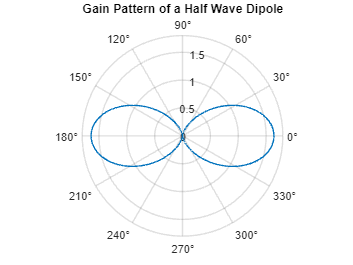

%G = (1.67.*sin(theta).^3)
theta_rotate = theta+pi./2;
G = 1.64.*(cos(cos(theta_rotate).*pi./2).^2)./(sin(theta_rotate).^2); %Half-Wave Dipole
%G = (3./2).*sin(theta).^2;                             % 
figure
polarplot(theta, G)
hold on
title('Gain Pattern of a Half Wave Dipole');
hold off

#### Ordinary End-Fire Arrays

An ordinary end-fire array is characterized by an N-element array of equally spaced antennas. Each antenna are identical and of equally magnitude. The ordinary end-fire array can only be modified by the number of elements in the array and the distance between each element. The spacing determines if the antenna will point in both directions, or in only one direction.

N = 10;                                                % Number of elements in the array
d = [lambda/2;lambda/4;lambda/6;lambda];      % Distance between each antenna element
k = 2.*pi./lambda;                                     % Wave number

The phase shift for an ordinary end fire array is equal to $\beta = -kd$ for $\theta = 0$ and $\beta = kd$° for $\theta = 180$°. It is not influenced by the number of elements.

beta = k.*d;                                           % Phase Shift
psi = (k*d.*cos(theta) + beta);                          
AF_n_ordinary = abs((sin(psi.*N./2) ./ sin(.5.*psi) ));
AF_n_ordinary_norm = (AF_n_ordinary./N);      % Array Factor

You can visibly see in this plot how the distance between antenna elements affects the overall pattern of the array factor. For the antenna to have major lobes pointing at both ends, the space between the elements should be $d = \lambda/2, \lambda, n\lambda$ where $n = 1,2,3,...$. 

However, the further the distance between the elements, the more high intensity lobes will appear.

Ideally, a proper ordinary end-fire array should have spacing at most $\lambda/2$

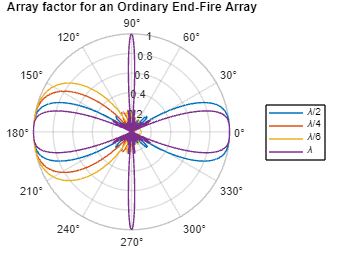

figure
polarplot(theta,AF_n_ordinary_norm);
hold on
title('Array factor for an Ordinary End-Fire Array');
legend('\lambda/2','\lambda/4','\lambda/6','\lambda');
hold off

#### Hanson-Woodyard End-Fire Array

The Hansen-Woodyard Array is a modified form of the Ordinary End-fire array. It features a progressive phase shift that is influenced by the number of elements.

$\beta = -(kd + \frac{2.92}{N})$ for $\theta = 0$°

$\beta = +(kd + \frac{2.92}{N})$ for $\theta = 180$°

The distance between elements is also influenced by the number of elements - the smaller amount of elements, the closer together. The higher number, the closer to $d \approx \lambda/4$.


$$d = (\frac{N-1}{N})\frac{\lambda}{4}$$
 
$$\approx \frac{\lambda}{4}$$


This design is useful for large N. We can see this with the by using the model for small N. 

#### Parameters:

f = 2*10^9;                 % Frequency
c = 3*10^8;                 % Speed of Light
lambda = c/f;               % Wavelenght
k = 2*pi/lambda;            % Wave Number
theta = 0:.00001:2*pi;      % Angle (theta)

N = [2;4;10];
d = ((N-1)./N).*(lambda./4);        % Distance between each antenna element
beta = k.*d + 2.94./N;              % Phase Shift
psi = k.*d.*cos(theta) + beta;      % Relative Phase
AF_N = abs((sin(psi.*N./2) ./ sin(.5.*psi) ));
Max = [max(AF_N(1,:)); max(AF_N(2,:)); max(AF_N(3,:))];
AF_HW = abs(AF_N)./Max;

The directivity is low. The main beams are so wide that an ordinary end-fire array would be preferred over the Hansen-Woodyard.

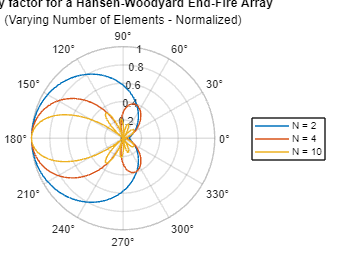

figure(3)
polarplot(theta,AF_HW);
hold on
title('Array factor for a Hansen-Woodyard End-Fire Array','(Varying Number of Elements - Normalized)')
legend('N = 2','N = 4','N = 10');
hold off

For this analysis, I found that making $N \geq 10$ allows for a much fairer comparison between the two array designs, so onward I will be using 10-element arrays.

#### Comparing the distance formula and the proposed $\lambda/4$ between each element.

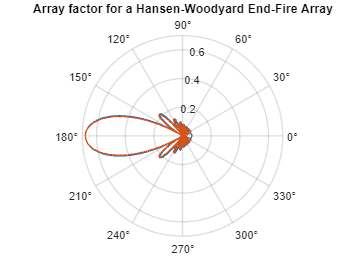

N = 15;
d = [((N-1)./N).*(lambda./4);lambda/4];                  % Distance between each antenna element
beta = k.*d + 2.94./N;                        % Phase Shift
psi = k*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi)*N;
AF_N = abs(AF_num./AF_den);

figure(4)
polarplot(theta,AF_N);
hold on
title('Array factor for a Hansen-Woodyard End-Fire Array')
hold off

#### Effect of the distance between elements and the backlobe

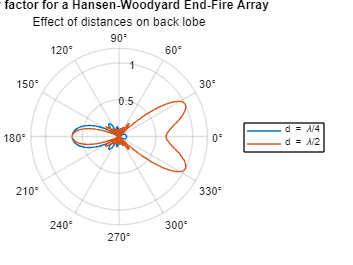

N = 10;
d = [lambda./4;lambda/2];                  % Distance between each antenna element
beta = (k.*d + pi./N);                        % Phase Shift
psi = k*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi);
AF_N = abs(AF_num./AF_den);
AF_N_norm = AF_N.*(1/N);

figure(5)
polarplot(theta,AF_N_norm);
hold on
title('Array factor for a Hansen-Woodyard End-Fire Array','Effect of distances on back lobe')
legend('d = \lambda/4','d = \lambda/2');
hold off

### Comparing the Hansen-Woodyard End-fire array with the Ordinary End-fire array

theta = -pi:.00001:pi; 
N = 10;
d = lambda/4;                  % Distance between each antenna element
beta_HW = (k.*d + pi./N);      % Phase Shift - HW
beta = k.*d;                   % Phase Shift - Ordinary
psi_ordinary = k*d.*cos(theta) + beta;  
psi_HW = k*d.*cos(theta) + beta_HW

psi_HW =     0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142    0.3142


psi = [psi_ordinary; psi_HW];
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi);
AF_N = abs(AF_num./AF_den);
AF_N_norm = AF_N(1,:).*(1/N);
AF_HW_Norm = AF_N(2,:)./(max(AF_N(2,:)))

AF_HW_Norm =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



Null_first_index = find(AF_HW_Norm<.05,1);
Null_first_index(1);
MainLobeBW = rad2deg(2*pi + 2*(theta(Null_first_index)))

MainLobeBW = 71.3734

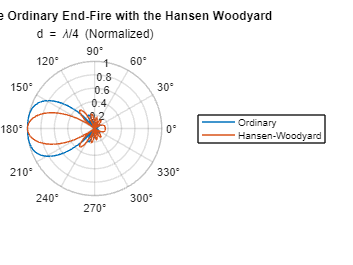



polarplot(theta,AF_N_norm);
hold on
polarplot(theta,AF_HW_Norm);
title('Comparing the Ordinary End-Fire with the Hansen Woodyard','d = \lambda/4 (Normalized)')
legend('Ordinary','Hansen-Woodyard');
hold off

What I find odd is using the given formula for the nromalized array factor, I do not get magnitude of 1. It goes against the concept of normalization.

#### Radiation Intensity of the Antenna Arrays

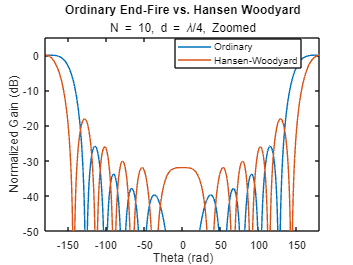

figure
plot(rad2deg(theta),mag2db(AF_N_norm.^2))
hold on
plot(rad2deg(theta), mag2db((AF_HW_Norm).^2))
xlim([-180 180])
ylim([-50 5])
title('Ordinary End-Fire vs. Hansen Woodyard','N = 10, d = \lambda/4')
legend('Ordinary','Hansen-Woodyard');
legend("Position", [0.55,0.8,0.25,0.0])
xlabel('Theta (rad)');
ylabel('Normalized Gain (dB)')
hold off

Effect of distance between each element and the back lobe

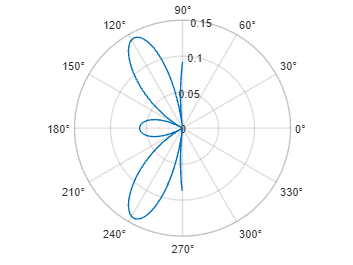

theta = pi/2:lambda/10:3*pi/2;      % Angle (theta)
N = 10;
a = size(theta,2);
% d = [2*lambda;lambda;lambda/2;lambda/4;lambda/6];                  % Distance between each antenna element
d = 0:2*lambda/a:2*lambda;
d = d(1:end-1).';
beta = -(k.*d + pi./N);                        % Phase Shift
psi = k.*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(psi./2);
AF_N = abs(AF_num./(AF_den.*N));
peak = max(AF_N);

figure
polarplot(theta, AF_N(15,:))

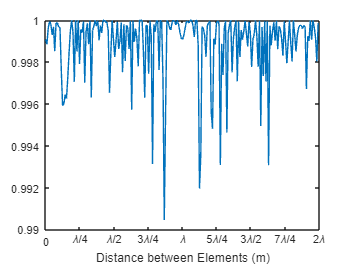

figure
plot(d,peak)
hold on
xlabel('Distance between Elements (m)')
set(gca,'Xtick',0:lambda/4:2*lambda,'XTickLabel',{'0','\lambda/4','\lambda/2','3\lambda/4','\lambda','5\lambda/4','3\lambda/2','7\lambda/4','2\lambda'});
hold off

theta = pi/2:lambda/5:3*2*pi;      % Angle (theta)
N = 10;
a = size(theta,2);
G = 1.64.*(cos(cos(theta+pi/2).*pi./2).^2)./(sin(theta+pi/2).^2); %Half-Wave Dipole

d = 0:2*lambda/a:2*lambda;
d = d(1:end-1).';
beta = -(k.*d + pi./N);                        % Phase Shift
psi = k.*d.*cos(theta) + beta;
AF_num = sin(psi.*N./2);
AF_den = sin(.5.*psi);
AF_N = abs(AF_num./AF_den)./N;
Pattern = G.*AF_N;
peak = max(Pattern);

N = [1,2,3,4,5]

N =      1     2     3     4     5


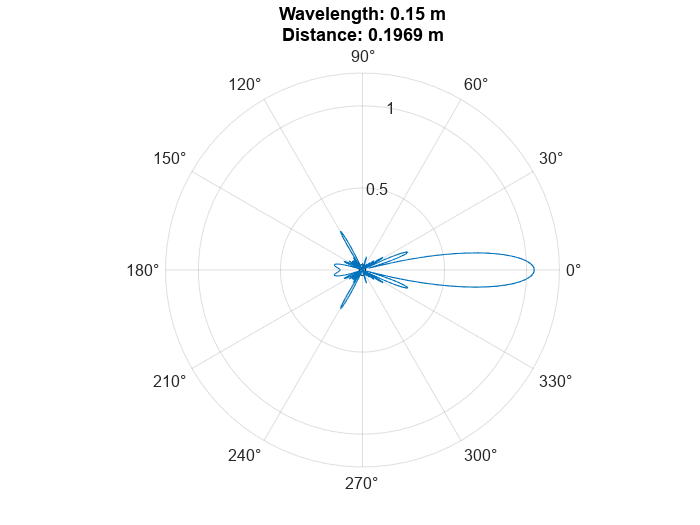

dipole_pos = d.*N;
Y = ones(1,5);

for i=1:size(theta,2)

    polarplot(theta,Pattern(i,:))
    	h = title({sprintf('Wavelength: %.2f m',lambda);sprintf('Distance: %.4f m',d(i))}); % title is 13 chars in both cases        
    drawnow
    pause(.1)
end

#### Optimizing the ordinary end-fire array

We want to maximize the directivity of our antenna, which means we want to minimize the beamwidth of our main lobe. Decreasing the half power beamwidth (HPBW)

lambda = 0.15;
N = 10;
learning_rate = 0.1
k = 2.* pi/lambda
d = .05
input_d = lambda/10:lambda/100:.05;

The HPBW approximation for an ordinary endfire is applicable when $\frac{\pi d}{\lambda} << 1$. This means that the distance between our elements are a limited range.

Qualify = pi.*input_d./lambda
plot(input_d,Qualify)
hold on
yline(1,'r')
xlim([.015,.075])
hold off

HPBW = 2.*acos(1 - (1.39.* lambda./(pi.*N.*input_d)))
plot(input_d, rad2deg(HPBW))
hold on
xlabel('Distance between elements (m)')
ylabel('HPBW (degrees)');
title('Approximated Half Power Beamwidth (HPBW)','as distance between elements is varied');
hold off

When using a simple approach as this, the smallest we can get our beamwidth, if we are being generous with what counts as what is much less than 1, is around 60 degrees.

beta = k.*d;                                           % Phase Shift
psi = (k*d.*cos(theta) + beta);                          
AF_n_ordinary = abs((sin(psi.*N./2) ./ sin(.5.*psi) ));
AF_n_ordinary_norm = (AF_n_ordinary./N);      % Array Factor
figure(3)
polarplot(theta,AF_n_ordinary_norm);
hold on
title('Array factor for an Ordinary End-Fire Array','d = 0.05 m');
hold off

syms d_change
HPBW_sym = 2.*acos(1 - (1.39.* lambda./(pi.*N.*d_change)))
HPBW_p1 = diff(HPBW_sym)
HPBW = subs(HPBW_p1,d_change,input_d)

#### Optimized Array:

Using the design parameters estimated from the gradient descent algorithm.

f = 2*10^9;                 % Frequency
N =10

N = 10

c = 3*10^8;                 % Speed of Light
lambda = c/f;               % Wavelenght
k = 2*pi/lambda;            % Wave Number
theta = 0:.01:2*pi;         % Angle (theta)
d_opt=1.05                  %Proposed distance

d_opt = 1.0500

beta_opt=3.17                 %proposed phase shift

beta_opt = 3.1700

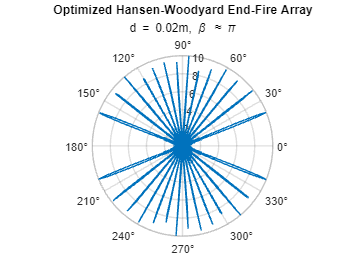


d = lambda/4;                  % Distance between each antenna element
beta_HW = (k.*d + pi./N);      % Phase Shift - HW


%Optimized
opt_AF = sin((k.*d_opt.*cos(theta) + beta_opt).*N./2)./ sin(.5.*(k.*d_opt.*cos(theta) + +beta_opt));
HW_AF = sin((k.*d.*cos(theta) + beta_HW).*N./2)./ sin(.5.*(k.*d.*cos(theta) + +beta_HW));

polarplot(theta,abs(opt_AF))
hold on
title('Optimized Hansen-Woodyard End-Fire Array','d = 0.02m, \beta \approx \pi');
hold off

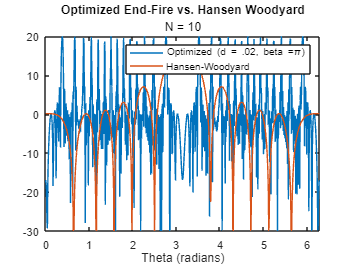


plot(theta, mag2db(abs(opt_AF)))
hold on
title('Optimized End-Fire vs. Hansen Woodyard','N = 10')

plot(theta, mag2db(abs(HW_AF)))
xlabel('Theta (radians)')
xlim([0 2*pi])
ylim([-30 20])
legend('Optimized (d = .02, beta =\pi)','Hansen-Woodyard');
hold off